### Parameter initialisation

Type your own CID in the field below:

clear
CID=002255390;
disp(['YOUR CID IS: ' num2str(CID)])

YOUR CID IS: 2255390


VDCrated=200;
Pbase=10e3;
Zbase=VDCrated^2/Pbase

Zbase = 4

N_rfilt=0.0225*Zbase

N_rfilt = 0.0900

N_r12=Zbase*0.0125

N_r12 = 0.0500

N_r13=Zbase*0.01

N_r13 = 0.0400

N_rv1=0.1*Zbase

N_rv1 = 0.4000

N_rv2=0.1*Zbase

N_rv2 = 0.4000

N_rv3=0.1*Zbase

N_rv3 = 0.4000

### Test of fixed voltage and current references:

This is a simple example to calculate the error between the desired power exchange in the interconnection network and the actual power exchange for a given interconnection network control algorithm. 

The calculation in the example code below is based on the trivial method that sets the voltage references to be equal to the nominal voltage of the network and the obtains the current references by dividing the power references by the rated voltage.

The results for the example case show that the voltage of the buses is quite close to the nominal voltage of the network but the power exchanges are very far from where they should be.

P1ref=Pbase;
P2ref=-Pbase/2;
P3ref=-P1ref-P2ref;

voff1=VDCrated;
voff2=VDCrated;
voff3=VDCrated;


iref1=P1ref/VDCrated;
iref2=P2ref/VDCrated;
iref3=P3ref/VDCrated;

disp('We run a simulation of the response to a fixed voltage and current reference:')

We run a simulation of the response to a fixed voltage and current reference:


out=sim('fixed_references_test_model.slx');

disp('The intended power exchanges were:')

The intended power exchanges were:


P1ref

P1ref = 10000

P2ref

P2ref = -5000

P3ref

P3ref = -5000

disp('The actual power exchanges obtained were:')

The actual power exchanges obtained were:


out.sim_P1

ans = 8.1419e+03

out.sim_P2

ans = -3.8680e+03

out.sim_P3

ans = -4.0129e+03

disp('The power exchange error, in pu, relative to the base power is:')

The power exchange error, in pu, relative to the base power is:


errP1=(out.sim_P1-P1ref)/Pbase

errP1 = -0.1858

errP2=(out.sim_P2-P2ref)/Pbase

errP2 = 0.1132

errP3=(out.sim_P3-P3ref)/Pbase

errP3 = 0.0987

disp('The mean square error of the power exchange is:')

The mean square error of the power exchange is:


err=sqrt((errP1^2+errP2^2+errP3^2)/3)

err = 0.1379


disp('The rated voltage of the network is:')

The rated voltage of the network is:


VDCrated

VDCrated = 200

disp('The actual voltages of the three buses of the network are:')

The actual voltages of the three buses of the network are:


out.sim_Vo1

ans = 200.6553

out.sim_Vo2

ans = 199.5153

out.sim_Vo3

ans = 199.8831

disp('The voltage error, in pu, relative to the nominal voltage is:')

The voltage error, in pu, relative to the nominal voltage is:


errVo1=(out.sim_Vo1-VDCrated)/VDCrated

errVo1 = 0.0033

errVo2=(out.sim_Vo2-VDCrated)/VDCrated

errVo2 = -0.0024

errVo3=(out.sim_Vo3-VDCrated)/VDCrated

errVo3 = -5.8459e-04

disp('The mean square error of the voltages is:')

The mean square error of the voltages is:


err=sqrt((errVo1^2+errVo2^2+errVo3^2)/3)

err = 0.0024

### Final test for a range of different power setpoints

The code below uses the full system model to simulate the operation of the system over 10 settlement periods. You can use this code to assess how well your network control algorithm works. The time series of power setpoints depends on your CID so make sure that the CID variable at the beginning of this livescript is properly set to match your CID.

rng(CID);
seriesP1ref=rand(10,1)*Pbase-Pbase/2

seriesP1ref = 1.0e+03 *

    2.0445
    4.1299
   -0.6350
   -3.8441
    2.6146
   -3.0816
   -1.3210
   -4.6356
   -0.7164
    1.2552


seriesP2ref=rand(10,1)*Pbase-Pbase/2

seriesP2ref = 1.0e+03 *

   -2.6772
   -4.7530
    0.2564
    1.4298
    3.1992
    4.5707
   -4.8313
    1.5422
    4.6979
    3.0665


seriesP3ref=-seriesP1ref-seriesP2ref

seriesP3ref = 1.0e+03 *

    0.6327
    0.6231
    0.3786
    2.4144
   -5.8137
   -1.4891
    6.1523
    3.0934
   -3.9816
   -4.3217



disp('We run a simulation of the response to series of power setpoints sent from the EMS:')

We run a simulation of the response to series of power setpoints sent from the EMS:


out=sim('m_full_system_model.slx');

  197.1624
  199.4758
  199.0634

  194.6668
  198.4932
  198.0851

  200.4640
  200.5304
  200.2850

  202.6915
  203.2482
  201.7039

  200.9761
  194.8691
  198.7476

  204.4725
  200.3769
  201.3430

  197.0701
  204.4150
  200.5023

  203.1109
  204.0191
  202.0480

  203.4967
  197.6459
  200.2647

  201.5208
  196.5317
  199.3904

  197.1624
  199.4758
  199.0634



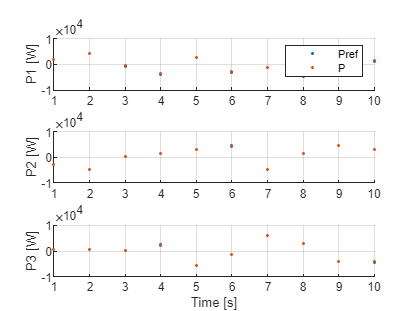

figure();
subplot(3,1,1);
scatter(1:10,seriesP1ref,'Marker','.','MarkerFaceColor','b')
hold on
scatter(1:10,out.sim_series_P1,'Marker','.','MarkerFaceColor','r')

axis([1 10 -Pbase, Pbase])
grid on;
ylabel('P1 [W]')
legend('Pref','P')
subplot(3,1,2);
scatter(1:10,seriesP2ref,'Marker','.','MarkerFaceColor','b')
hold on
scatter(1:10,out.sim_series_P2,'Marker','.','MarkerFaceColor','r')
axis([1 10 -Pbase, Pbase])
grid on;
ylabel('P2 [W]')

subplot(3,1,3);
scatter(1:10,seriesP3ref,'Marker','.','MarkerFaceColor','b')
hold on
scatter(1:10,out.sim_series_P3,'Marker','.','MarkerFaceColor','r')
axis([1 10 -Pbase, Pbase])
grid on;
ylabel('P3 [W]')
xlabel('Time [s]')


disp('The mean square error of the power exchange is')

The mean square error of the power exchange is


errseriesP1=(seriesP1ref-out.sim_series_P1)/Pbase;
errseriesP2=(seriesP2ref-out.sim_series_P2)/Pbase;
errseriesP3=(seriesP3ref-out.sim_series_P3)/Pbase;
errPseries=sqrt((errseriesP1.^2+errseriesP2.^2+errseriesP3.^2)/3)

errPseries =     0.0045
    0.0088
    0.0070
    0.0173
    0.0148
    0.0211
    0.0207
    0.0204
    0.0193
    0.0129


disp('The average of this for the entire sereis of operating conditions is:')

The average of this for the entire sereis of operating conditions is:


erravgPseries=sum(errPseries)/length(errPseries)

erravgPseries = 0.0147

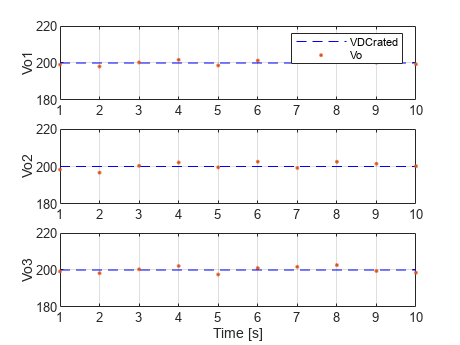


figure();
subplot(3,1,1);
plot([1,10],VDCrated*[1,1],'b--')
hold on;
scatter(1:10,out.sim_series_Vo1,'Marker','.','MarkerFaceColor','r')
axis([1 10 0.9*VDCrated 1.1*VDCrated])
grid on;
ylabel('Vo1')
legend('VDCrated','Vo')

subplot(3,1,2);
plot([1,10],VDCrated*[1,1],'b--')
hold on;
scatter(1:10,out.sim_series_Vo2,'Marker','.','MarkerFaceColor','r')
axis([1 10 0.9*VDCrated 1.1*VDCrated])
grid on;
ylabel('Vo2')

subplot(3,1,3);
plot([1,10],VDCrated*[1,1],'b--')
hold on;
scatter(1:10,out.sim_series_Vo3,'Marker','.','MarkerFaceColor','r')
axis([1 10 0.9*VDCrated 1.1*VDCrated])
grid on;
ylabel('Vo3')
xlabel('Time [s]')


disp('The mean square error of the voltage in pu')

The mean square error of the voltage in pu


errseriesVo1=(VDCrated-out.sim_series_Vo1)/VDCrated;
errseriesVo2=(VDCrated-out.sim_series_Vo2)/VDCrated;
errseriesVo3=(VDCrated-out.sim_series_Vo3)/VDCrated;
errVoseries=sqrt((errseriesVo1.^2+errseriesVo2.^2+errseriesVo3.^2)/3)

errVoseries =     0.0059
    0.0120
    0.0018
    0.0102
    0.0081
    0.0089
    0.0058
    0.0122
    0.0047
    0.0047


disp('The average of this for the entire sereis of operating conditions is:')

The average of this for the entire sereis of operating conditions is:


erravgVoseries=sum(errVoseries)/length(errVoseries)

erravgVoseries = 0.0074